# 串联滞后校正

G1=tf(10,[1 0]);
G21=tf(1,[0.05 1]);
G22=tf(1,[0.1 1]);
G2=series(G21,G22);
H=1;

## 1．计算串联校正装置的传递函数 Gc（s）和校正网络参数。

b=1/11;%分度系数,表示滞后深度
T=11;%时间常数
Gc=tf([b*T 1],[T 1]);
sprintf("校正网络参数b=%g,T=%g",b,T);
display(Gc);

Gc =
 
   s + 1
  --------
  11 s + 1
 
Continuous-time transfer function.



## 2．画出校正后系统的对数坐标图，并求出校正后系统的ω′c及ν′。

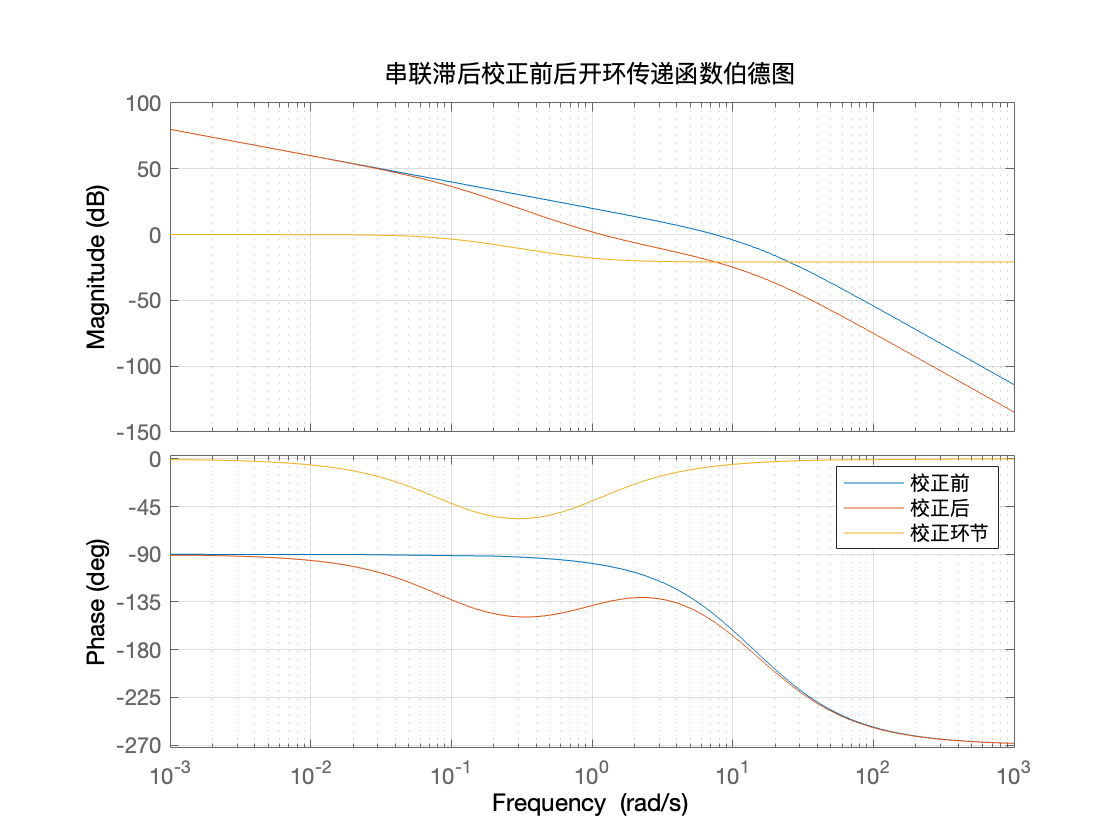

G_ori=series(G1,G2);
G_corr=series(Gc,G_ori);

figure();
bode(G_ori,G_corr,Gc);grid;
legend('校正前','校正后','校正环节');title('串联滞后校正前后开环传递函数伯德图');

[Gm_ori,Pm_ori] = margin(G_ori);%Gm: gain margin幅值裕度，单位为一 
[Gm_corr,Pm_corr] = margin(G_corr);%Pm: phase margin相角裕度
text=sprintf("校正前：幅值裕度：%g,相角裕度：%g\n校正后：幅值裕度：%g,相角裕度：%g" ...
    ,Gm_ori,Pm_ori,Gm_corr,Pm_corr)

text =     "校正前：幅值裕度：3,相角裕度：32.6133
     校正后：幅值裕度：28.486,相角裕度：44.0019"


## 3．比较校正前后系统的阶跃响应曲线及性能指标，说明校正装置的作用。

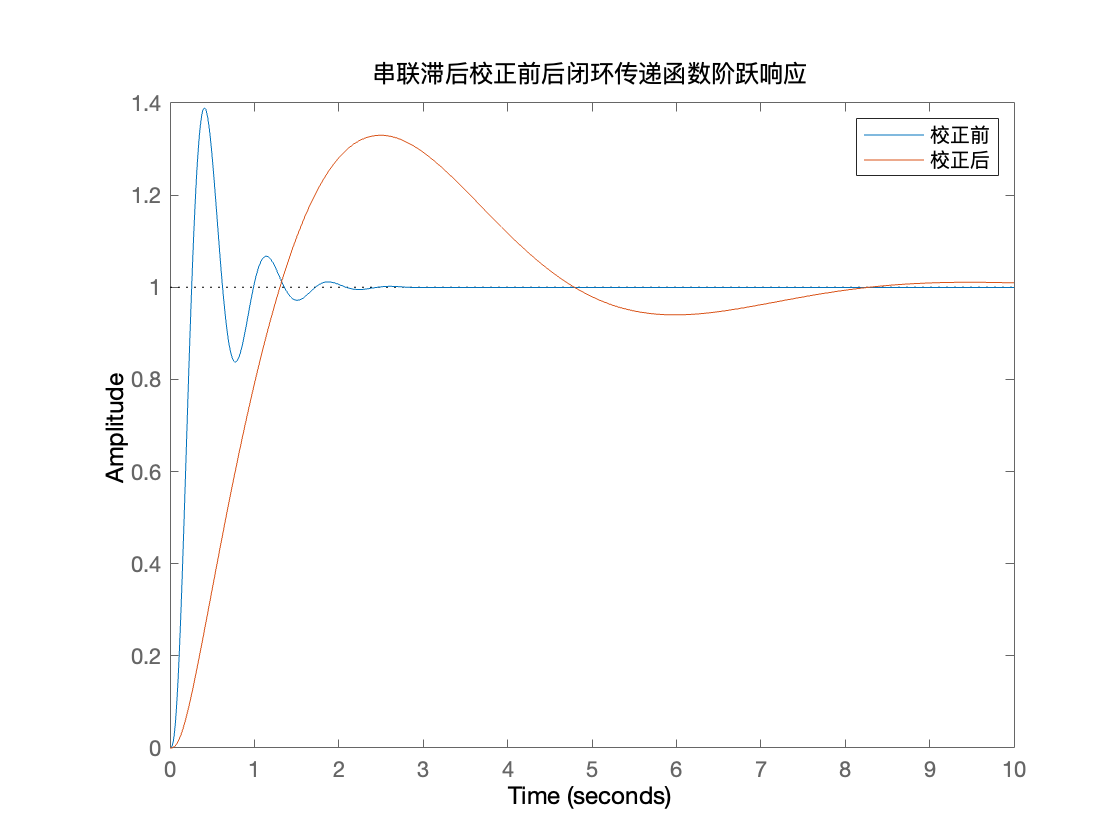

Phi_ori=feedback(G_ori,H);
Phi_corr=feedback(G_corr,H);
figure();
stepplot(Phi_ori,Phi_corr);
legend('校正前','校正后');title('串联滞后校正前后闭环传递函数阶跃响应');

info_ori=stepinfo(Phi_ori);
info_corr=stepinfo(Phi_corr);
struct2table([info_ori,info_corr])

ans = 2×8 table
    RiseTime    SettlingTime    SettlingMin    SettlingMax    Overshoot    Undershoot     Peak     PeakTime
    ________    ____________    ___________    ___________    _________    __________    ______    ________

    0.15654         1.601         0.83788        1.3894        38.942          0         1.3894    0.40912 
    0.91285        7.5306         0.90031          1.33        32.997          0           1.33      2.497 


## 参考链接🔗

- [What is Lag Compensator? Definition, Lag Angle, Advantages and Disadvantages of Lag Compensator - Electronics Coach](https://electronicscoach.com/lag-compensator.html)